**Laplace transform**

%CS lecutre 9

%Compute the Laplace transform 
clear all;

syms t s
syms a positive

ft_a=1;
ft_b= exp(-a*t);
ft_c=t;
ft_d=dirac(t-a);
ft_e=cos(t);
ft_f=t^2*exp(-a*t);
ft_g=exp(-a*t)*sin(t);

Fs_a=ilaplace(ft_a,t,s);
Fs_b=ilaplace(ft_b,t,s);
Fs_c=ilaplace(t,t,s);
Fs_d=ilaplace(dirac(t-a),t,s);
Fs_e=ilaplace(ft_e,t,s);
Fs_f=ilaplace(ft_f,t,s);
Fs_g=ilaplace(ft_g,t,s);

**Laplace transform 2**

$\left.\dot{\;f\left(\right.} t\right)$ > $\mathrm{sF}\left(s\right)-f\left(0\right)$

$\int_0^t f\left(\tau \right)d\tau$ > $\frac{F\left(s\right)}{s}$

$e^{\mathrm{at}} f\left(t\right)$ > $F\left(s-a\right)$

$f\left(t-a\right)H\left(t-a\right)$ > $e^{\mathrm{as}} F\left(s\right)$

clear all;
syms t tau f(t) g(t)
syms a positive

df=diff(f(t));
intt=int(subs(f(t),t,tau),tau,[0,t]);
fsft=exp(a*t)*f(t);
tsft=subs(f(t),t,t-a)*heaviside(t-a);

Fs_df = simplify(laplace(df));
Fs_intt = simplify(laplace(intt));
Fs_fsft = simplify(laplace(fsft));
Fs_tsft = simplify(laplace(tsft));

syms F(s)

Fs_df = subs(Fs_df,laplace(f(t),t,s),F(s))

$$Fs\_df = s\,F\left(s\right)-f\left(0\right)$$

Fs_intt = subs(Fs_intt,laplace(f(t),t,s),F(s))

$$Fs\_intt = \frac{F\left(s\right)}{s}$$

Fs_fsft = subs(Fs_fsft,laplace(f(t),t,s-a),F(s-a))

$$Fs\_fsft = F\left(s-a\right)$$

Fs_tsft = subs(Fs_tsft,laplace(f(t),t,s),F(s))

$$Fs\_tsft = {\mathrm{e}}^{-a\,s}\,F\left(s\right)$$

**Spring-damper System **

**ODE:**


$$m\ddot{\;x} +c\dot{\;x} +\mathrm{kx}=F$$


clear all;

syms x(t) X t s

m = 1; c = 2; k = 10; F = 1;

eqn = m*diff(x(t),2)+c*diff(x(t))+k*x(t)==F;

L_eqn = laplace(eqn)

$$L\_eqn = 2\,s\,\mathrm{laplace}\left(x\left(t\right),t,s\right)-2\,x\left(0\right)-s\,x\left(0\right)+s^{2}\,\mathrm{laplace}\left(x\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)+10\,\mathrm{laplace}\left(x\left(t\right),t,s\right)=\frac{1}{s}$$

L_eqn = subs(L_eqn,{laplace(x(t),t,s),x(0),diff(x(t))},{X,0,0})

$$L\_eqn = X\,s^{2}+2\,X\,s+10\,X=\frac{1}{s}$$


X = solve(L_eqn,X)

$$X = \frac{1}{s^{3}+2\,s^{2}+10\,s}$$

**Inverse Laplace**

syms x

x=ilaplace(X)

$$x = \frac{1}{10}-\frac{{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)+\frac{\sin\left(3\,t\right)}{3}\right)}{10}$$

**Plot the solutions**

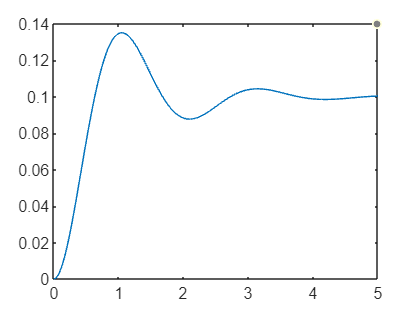

t_ = linspace(0,5,150);
plot(t_,subs(x,t,t_))

**Review**

clear all;

syms x(t) u(t) X U t s

m = 1 ; c = 2; k = 10;

eqn = m*diff(x(t),2)+c*diff(x(t))+k*x(t)==u(t)

$$eqn = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\frac{\partial }{\partial t}x\left(t\right)+10\,x\left(t\right)=u\left(t\right)$$

L_eqn = laplace(eqn)

$$L\_eqn = 2\,s\,\mathrm{laplace}\left(x\left(t\right),t,s\right)-2\,x\left(0\right)-s\,x\left(0\right)+s^{2}\,\mathrm{laplace}\left(x\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)+10\,\mathrm{laplace}\left(x\left(t\right),t,s\right)=\mathrm{laplace}\left(u\left(t\right),t,s\right)$$

L_eqn =subs(L_eqn,{laplace(x(t),t,s),x(0),diff(x(t)),laplace(u(t),t,s)}, ...
    {X,0,0,U})

$$L\_eqn = X\,s^{2}+2\,X\,s+10\,X=U$$

X=solve(L_eqn,X)

$$X = \frac{U}{s^{2}+2\,s+10}$$

TF=X/U

$$TF = \frac{1}{s^{2}+2\,s+10}$$


[n,d]=numden(TF) 

$$n = 1$$

$$d = s^{2}+2\,s+10$$

a=sym2poly(n) %계수들의 벡터를 구해줌

a = 1

b= sym2poly(d)

b =      1     2    10


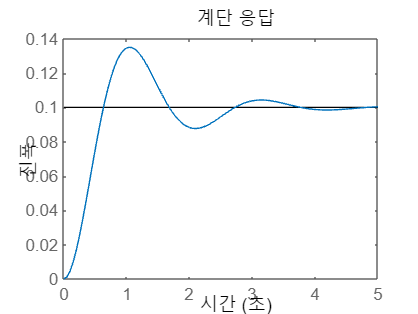


sys = tf(a,b);
step(sys,5)